# **IO3xx Serial - Loopback Halfduplex**

This example shows how to perform a loopback test using IO3xx Serial with the Serial Interrupt and halfduplex mode. You can test the basic IO3xx serial functionality by running this example.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- Speedgoat configuration file that supports **2x serial channels**

-     -->** serial version must be 2.11 or later**

-     --> serial interrupt must be connected in the configuration file

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

This example is a loopback on the serial channels 1-2 using half-duplex communication. The Tx pin of the first channel must be connected to the Tx pin of the second channel. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file used.

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. 

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Serial_Loopback_Halfduplex';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

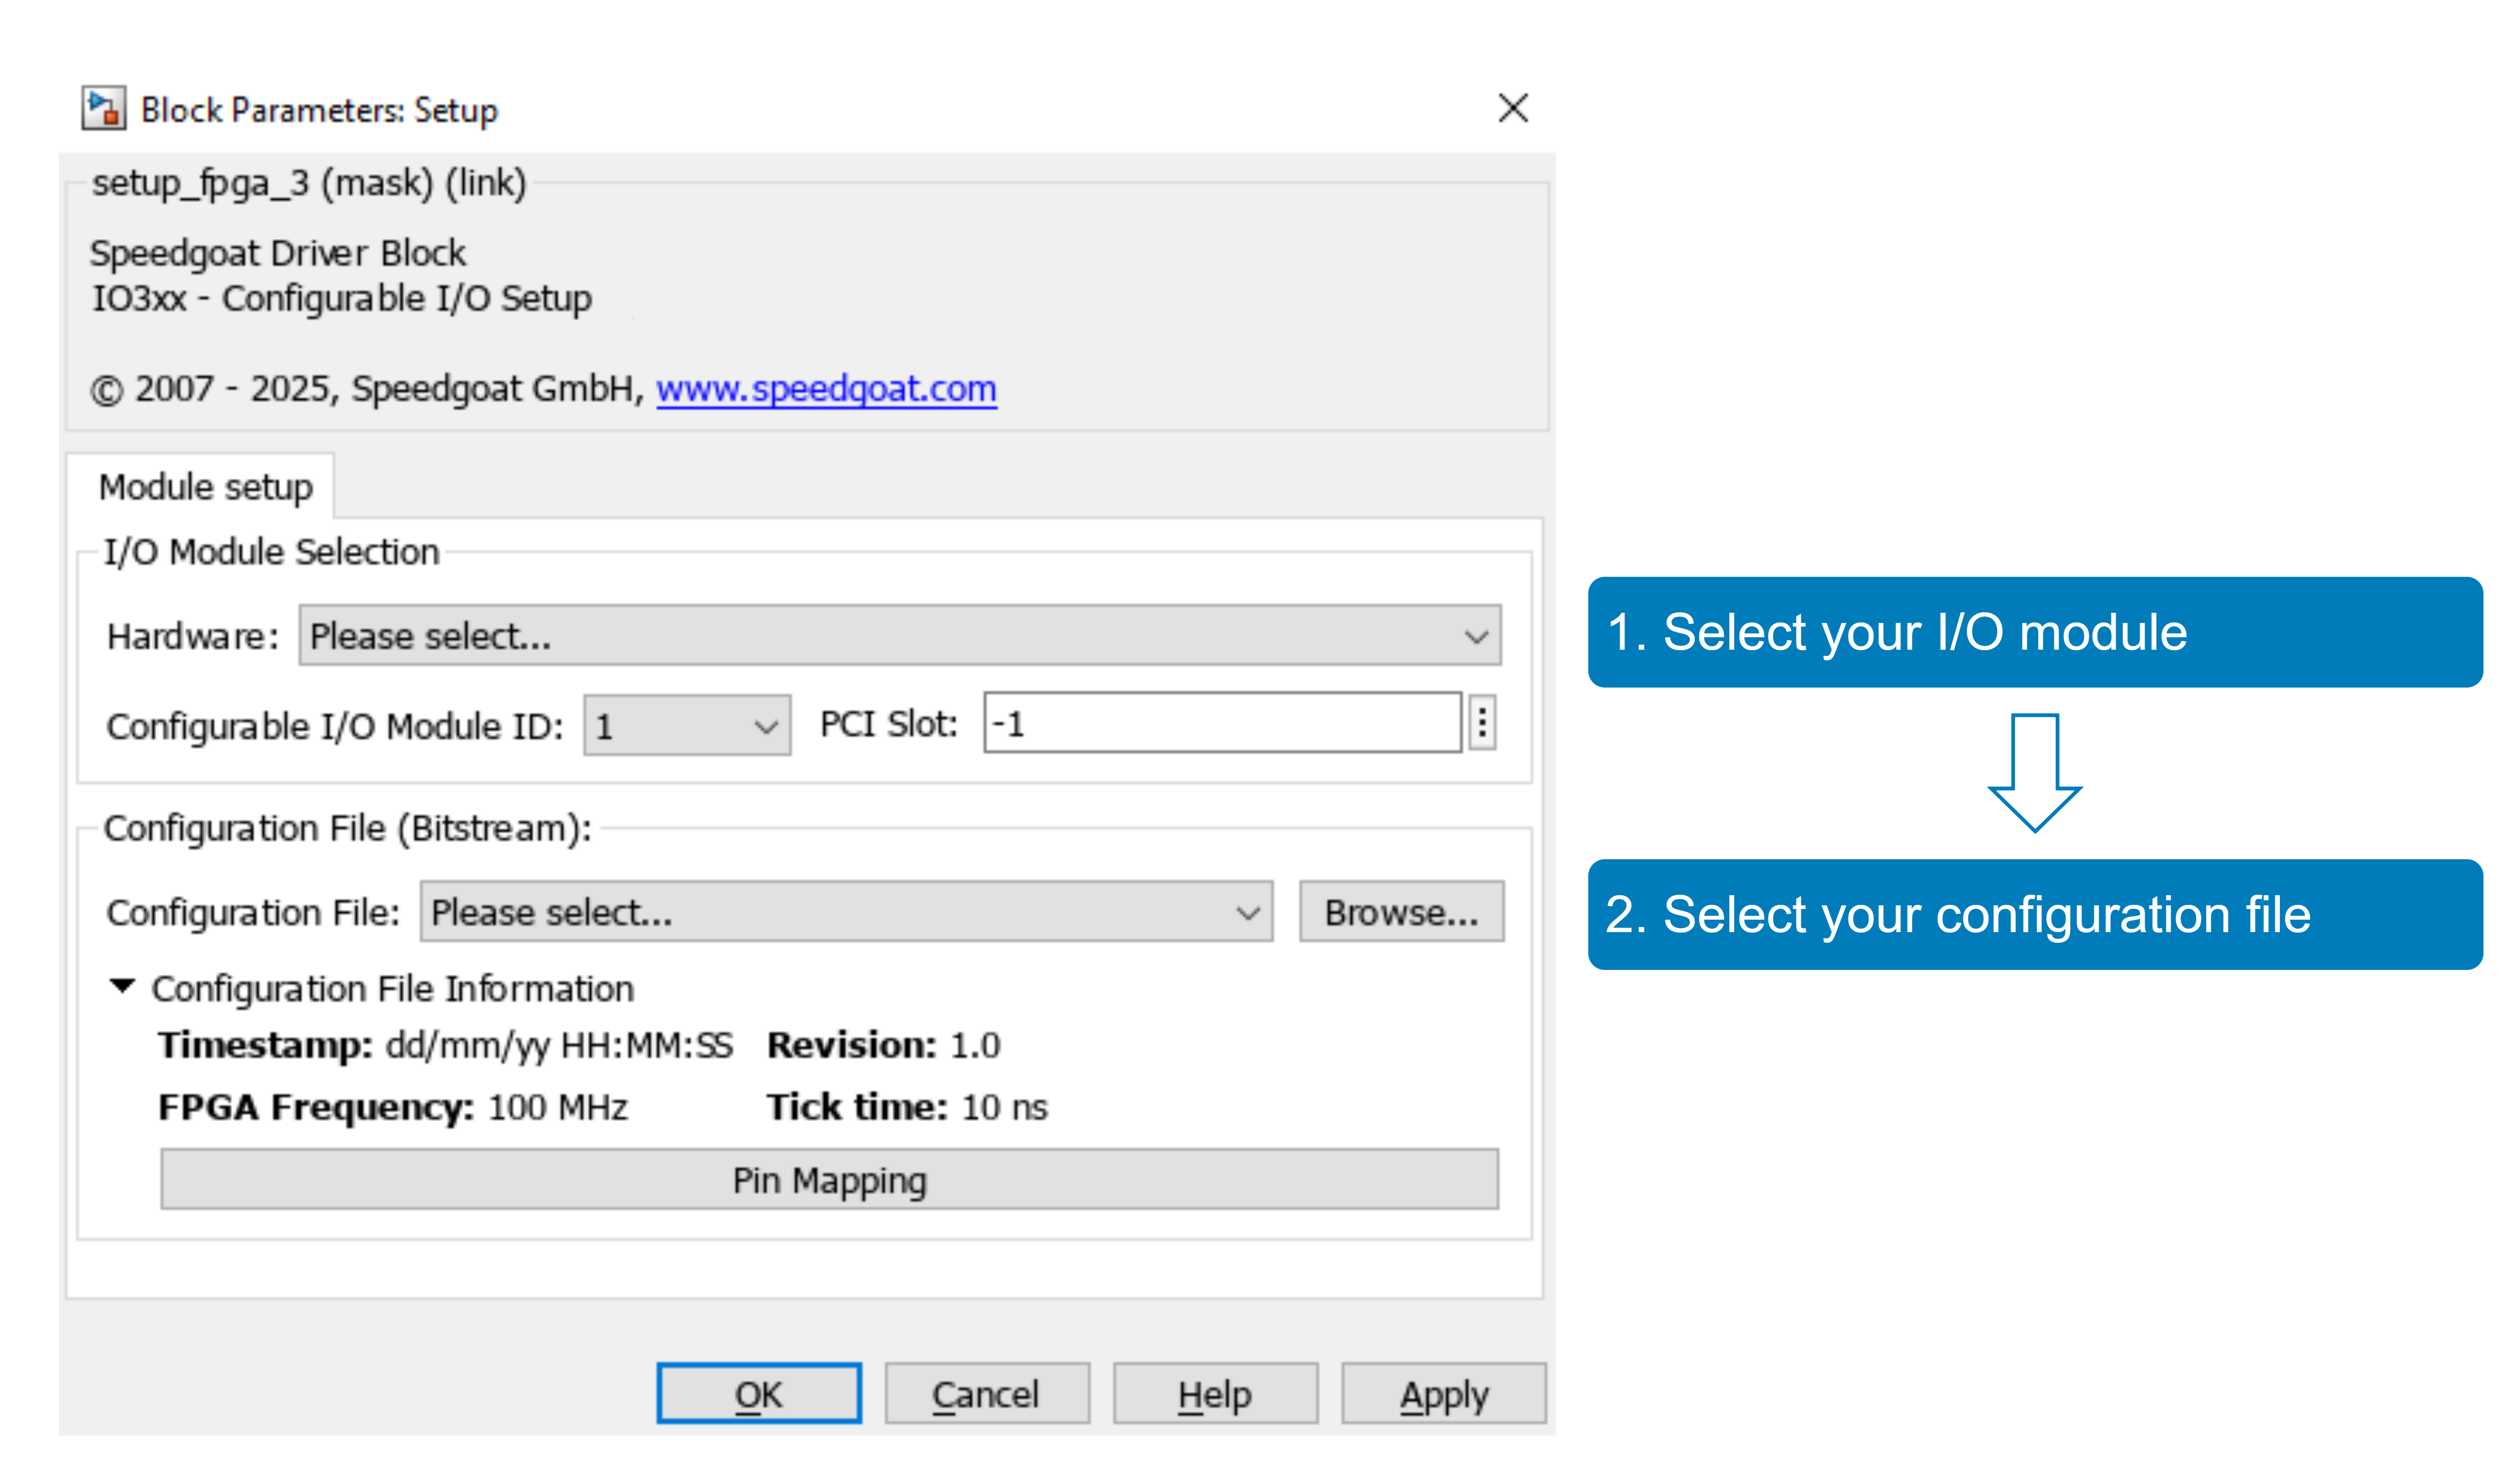

With the **Pin Mapping** button you can now check where the functionalities are located.

After you set your I/O module and the configuration file, you also need to select the correct Serial Interrupt source. To do so, double-click the Serial Interrupt Setup block, and select the corresponding "IO3xx Serial Interrupt" from the list:

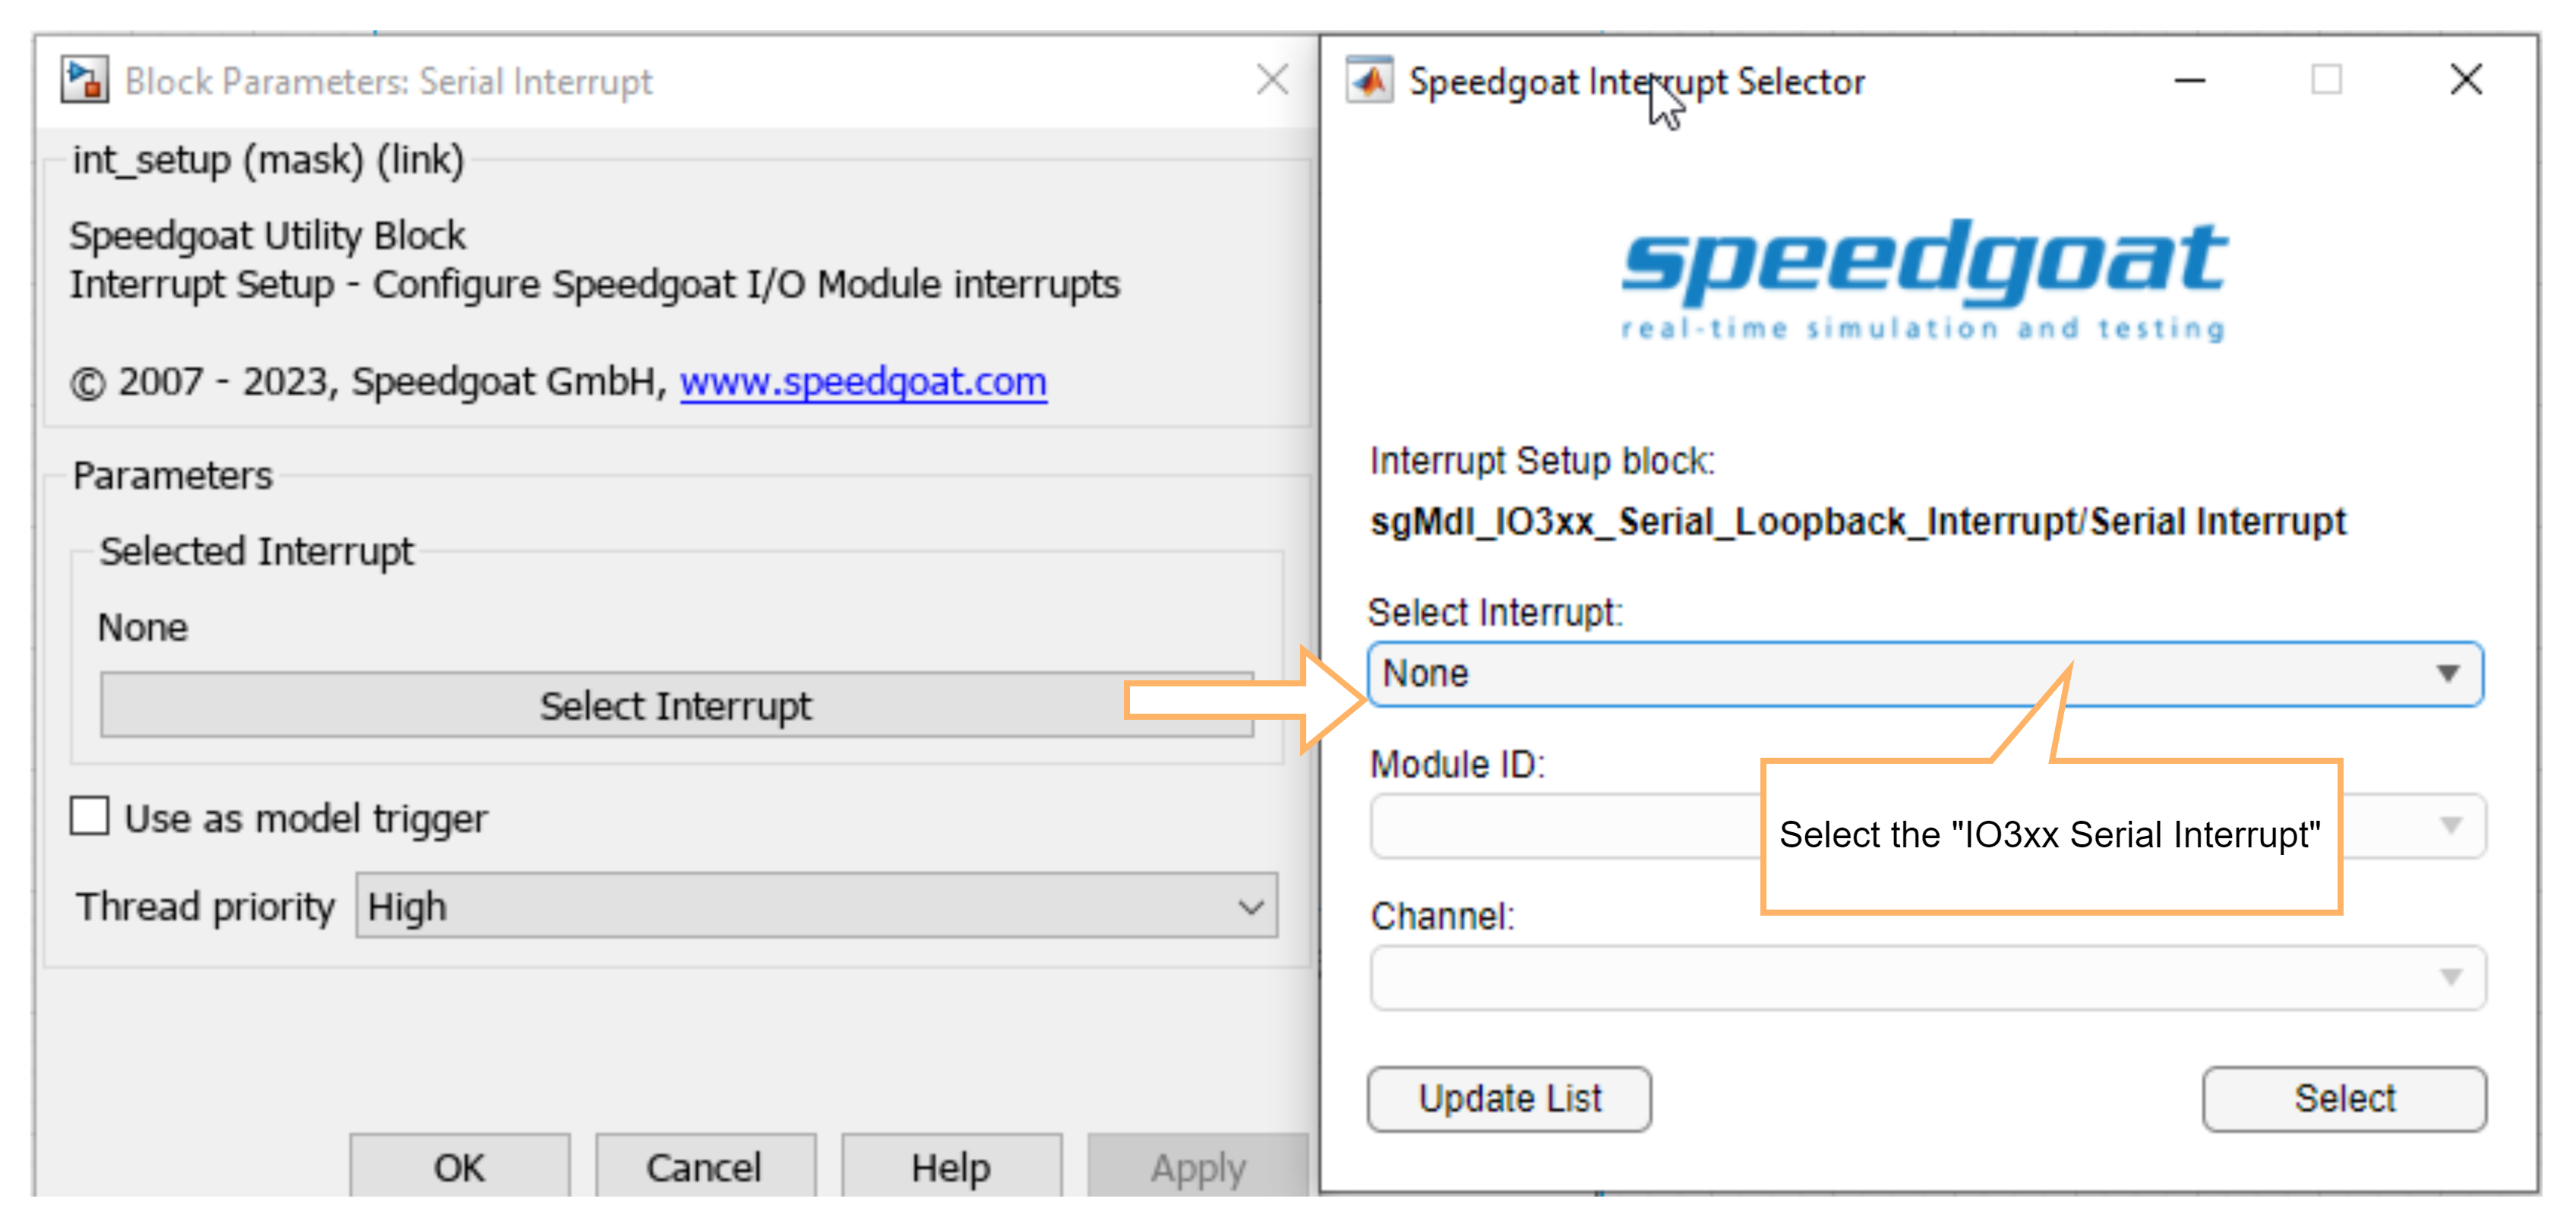

### Model Description

#### Half Duplex Communication in Combination with the Serial Interrupt

In this model, serial channel 1 is used as master and serial channel 2 as slave. In the [Serial Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_setup_v2) block, **Enable half duplex** is set so only the Tx line needs to be connected. Ensure that both serial channels do not send Tx data at the same time as this would result in a communication collision. The Serial Interrupt feature is used to read the values received. Serial channel 1 writes Tx data with the model step, while serial channel 2 receives and writes in the interrupt. The timing scheme is as follows:

- Model step: serial channel 1 writes Tx data.

- Serial channel 2 triggers the interrupt when the data have been received (open the triggered subsystem **Serial Read** to see the details)

- Serial channel 2 data are read and at the same time, serial channel 2 writes Tx data

- Serial channel 1 triggers the interrupt when the data have been received (open the triggered subsystem **Serial Read** to see the details)

- Serial channel 1 data are read

The following image shows the detailed timing diagram:

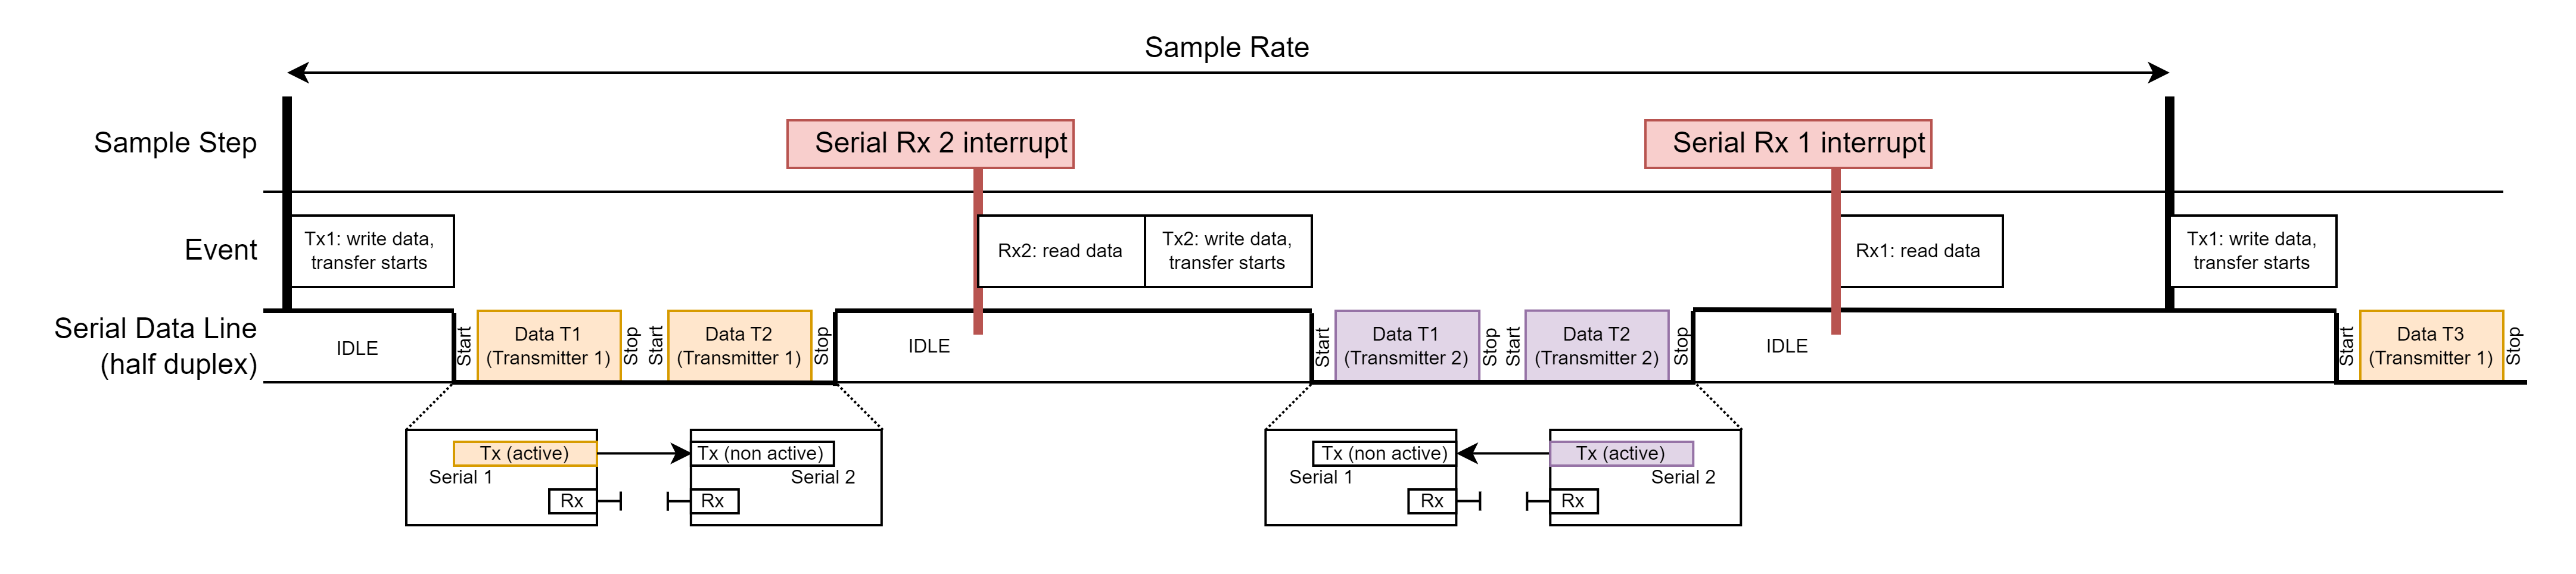

#### Model Details

In the **Master: Transmit** area, the serial channel 1 Tx data are defined which are sent to serial channel 2 so we can check the data.

The Serial Setup block defines the setup of the Serial transmitters and receivers. Serial channels 1 and 2 to be used are defined in the **Module Setup** tab. On the **Bitrate** tab, a transfer rate of 1 MBaud is set for all channels, and the **Enable half duplex** is also defined. The **UART frame** tab is used to set up the protocol details. In the **Timeout setup **tab we can define the timeout described above to trigger a serial interrupt. The timeout setting is defined in number of UART words. In this example, the baudrate is set to 1 MHz and the frame is defined as 8 data-bits and 2 stop-bits. 1 start-bit is always used. This means if we set the timeout to 1 and there is no activity on the serial Rx for more than 1/1 MHz * 11bits = 11 us, then the interrupt will be generated. The timeout for the 2 channels used is set to [1 1].

The Serial Interrupt block selects the Serial Interrupt source and generates an output port which then can be used to trigger the **Slave: Read and Transmit / Master: Read **subsystem.

The **Slave: Read and Transmit / Master: Read** subsystem contains the blocks required to read out and transfer the serial data of channel 2, and to read the serial data of channel 1. The Read Timeout Status block is required to be able to reset the pending serial Rx interrupts. This block also contains an output that indicates which of the serial channels triggered an interrupt. In this example, we are using serial channels 1 and 2. If serial channel 1 triggered the interrupt, element 1 in the output **Status** will be high. We therefore demux the Status output in the 2 channels used and connect them to a **Serial Rx1 and Serial Rx Tx 2 **enabled subsystem. These subsystems finally contain the **Serial Read HW FIFO **and **Serial Write HW FIFO** which are used to read out the Rx data (both channels) of the serial Rx FIFO, write Tx data, and start a new frame (channel 2 only).

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope connected to the Serial Read block. The scope must display the serial data:

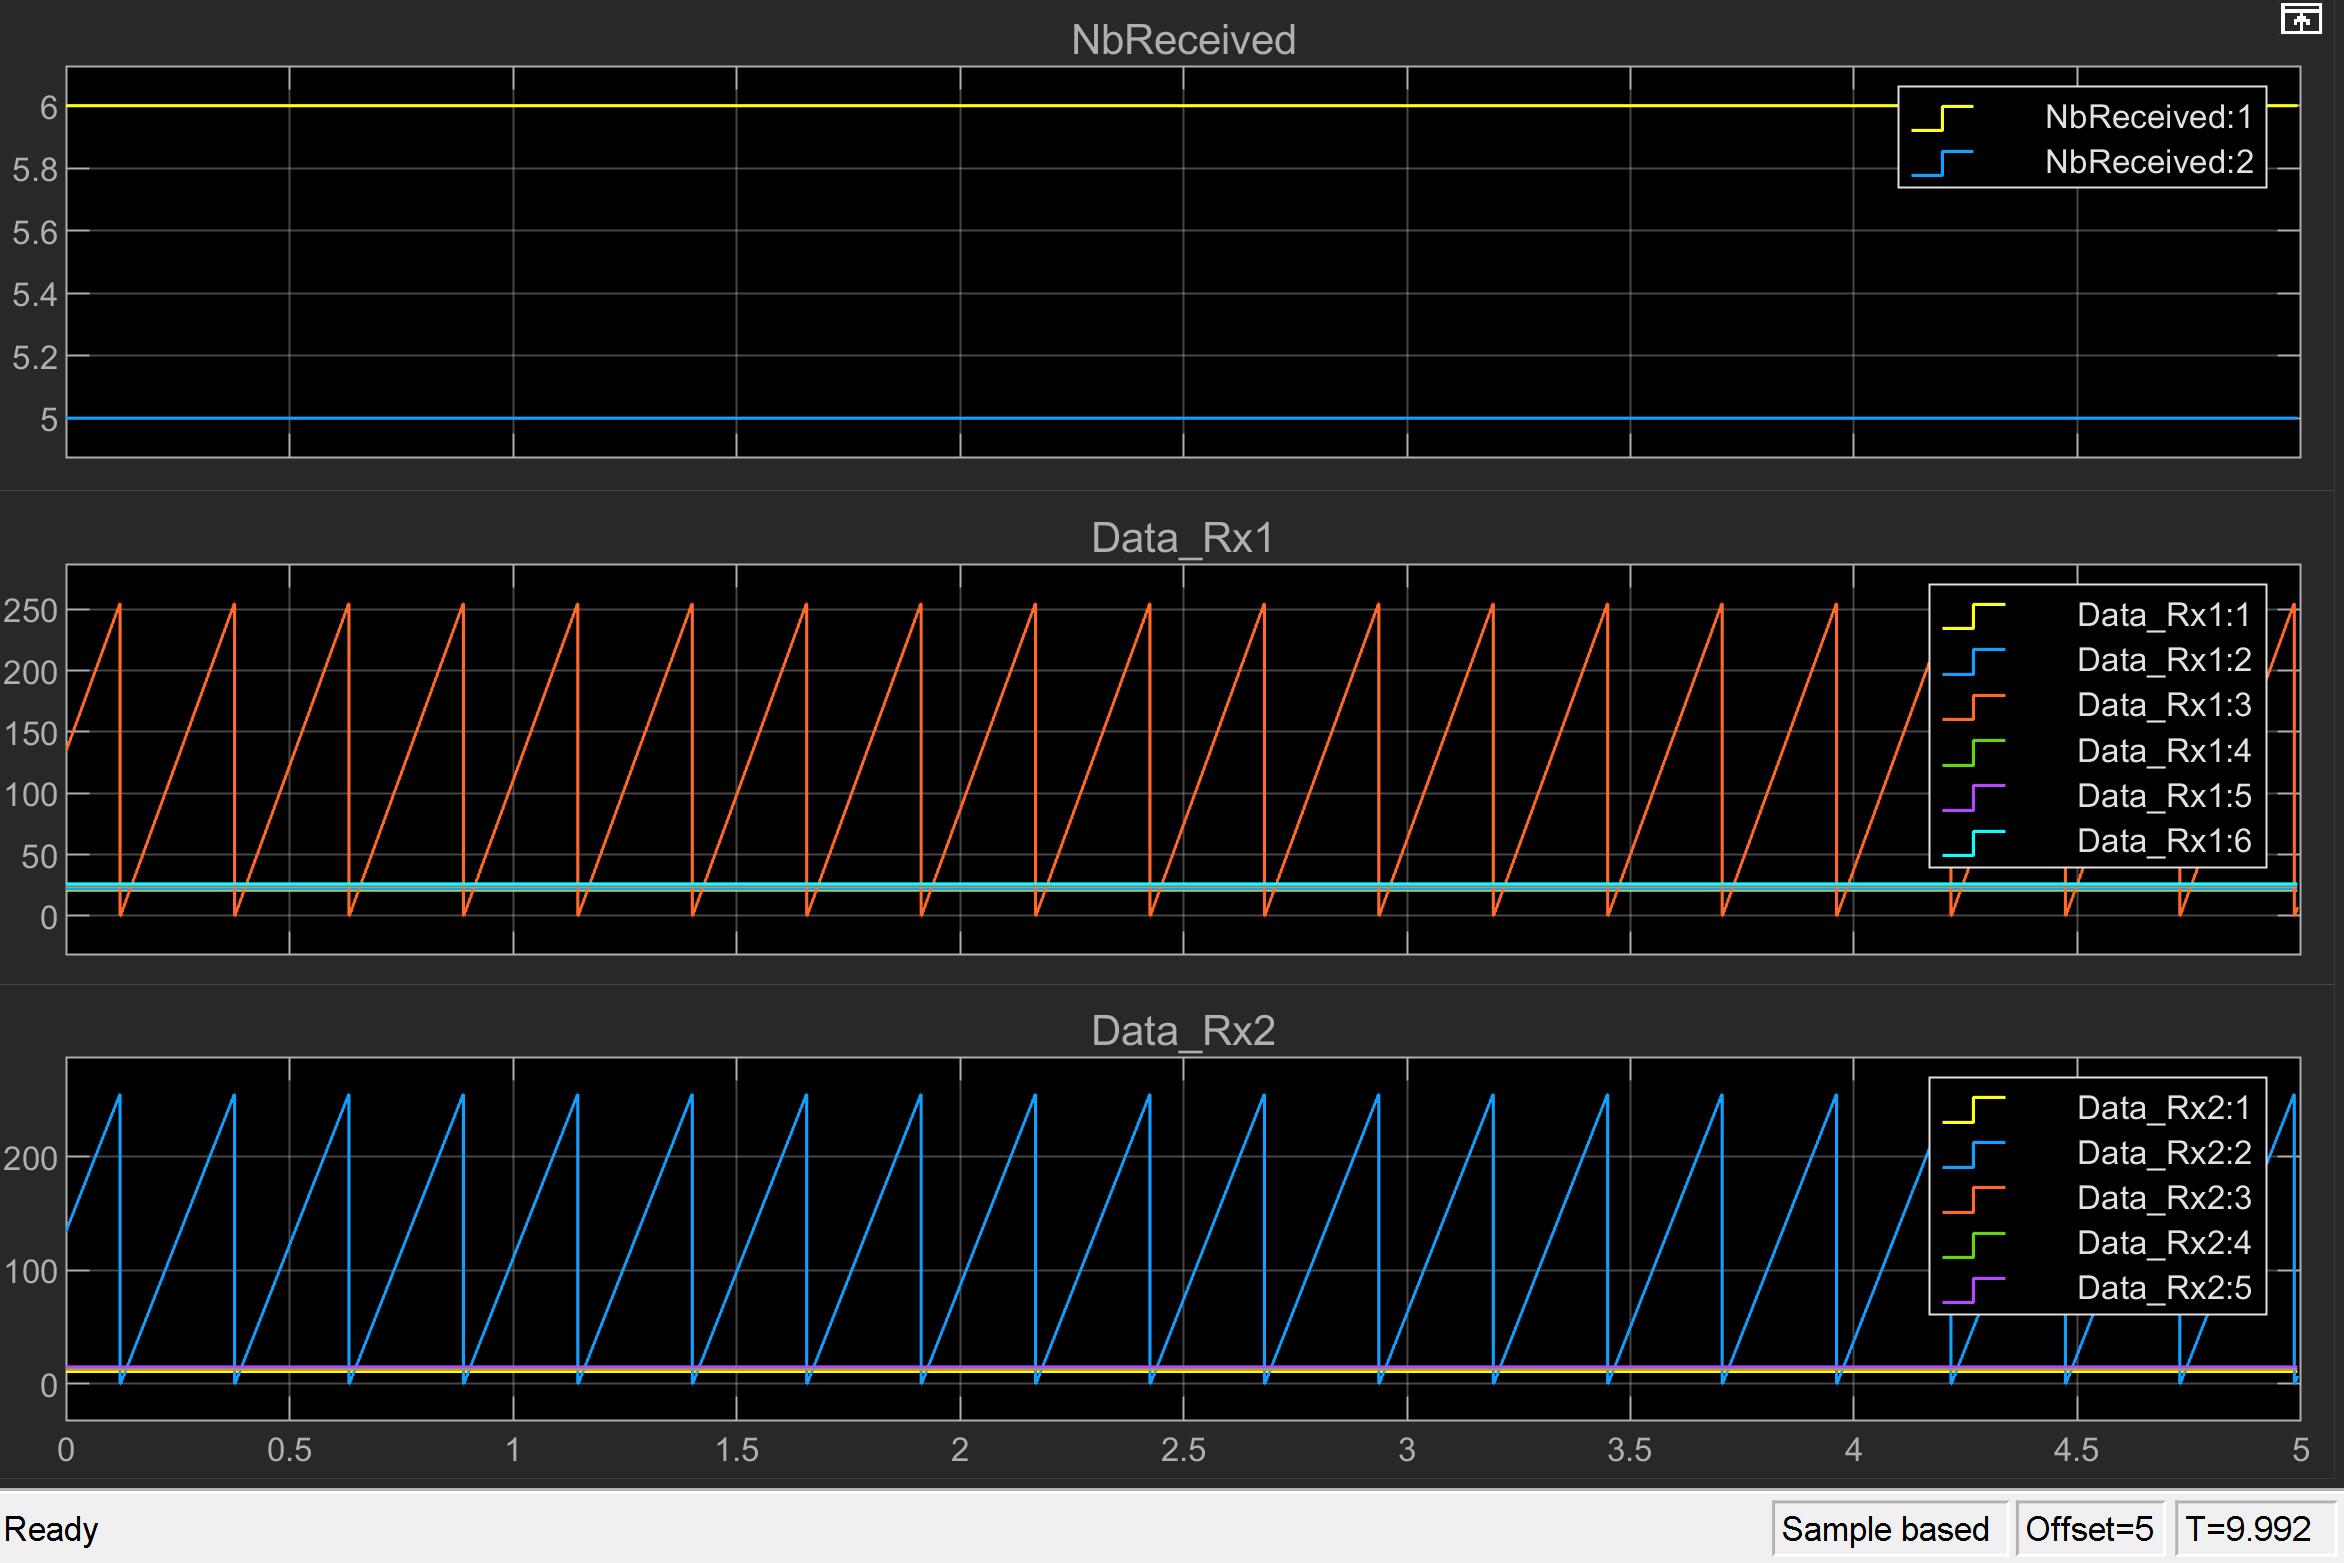

The **NbReceived** part shows the number of bytes received. The following values are expected:

- Channel 1: 6 Rx Data

- Channel 2: 5 Rx Data

The **Data_Rx1 **part displays the serial Rx channel 1 data received that has been sent from Tx channel 2:

- Data 1: fixed to decimal 21

- Data 2: fixed to decimal 22

- Data 3: free running counter

- Data 4 to 6: fixed to decimal 24, 25, 26

The **Data_Rx2** part displays the serial Rx channel 2 data received that has been sent from Tx channel 1:

- Data 1: fixed to decimal 11

- Data 2: free running counter

- Data 3 to 5: fixed to decimal 13, 14, 15

## Additional References

- [IO3xx Serial documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_serial)